# **Controls for parameter tuning**

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

## Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-10-01_exp_1\2019-10-01_exp_1.mat')


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


# 1. Test the role of various tuning parameters

use_classifier  = false;
method          = 'linear';

## Test 1.1 : Test how the Kfold setting (for training) affect the prediction

Changing KFold for the training set from 2 to 10 (color scheme), with 10 iterations (individual points as scatter), et for two behaviours

kfold_range = 2:10; result_kfold = {};
for idx = 1:numel(kfold_range)      
    out = {}; disp(idx)
    parfor iter = 1:10
        out{iter} = predict_behaviours(obj, use_classifier, method, 'peaks_subtracted',{'trigger','encoder'}, '', 'kfold', kfold_range(idx));
    end
    result_kfold{idx} = out;%cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', out, 'UniformOutput', false));
end

     1



total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-exc

     2



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0185%
The out-of-sample misclassification rate is 7.35%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     3



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0146%
The out-of-sample misclassification rate is 6.82%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     4



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0156%
The out-of-sample misclassification rate is 9.46%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     5



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0167%
The out-of-sample misclassification rate is 7.35%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     6



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0163%
The out-of-sample misclassification rate is 6.66%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     7



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0145%
The out-of-sample misclassification rate is 6.39%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     8



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0201%
The out-of-sample misclassification rate is 6.72%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     9



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0159%
The out-of-sample misclassification rate is 6.19%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

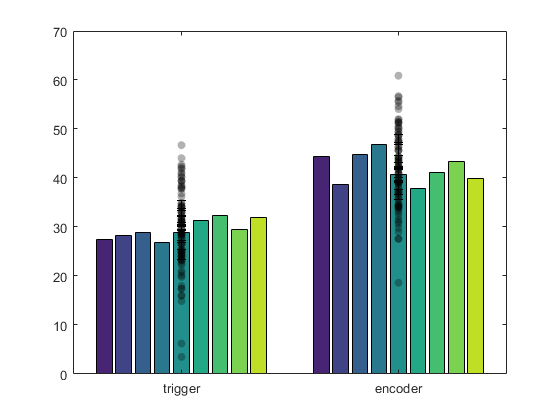

bar_chart(result_kfold);

## Test 1.2 : Test how the Holdout setting affect the prediction

Changing the holdout paramater from 0.1 to 0.9 (color scheme), with 10 iterations (individual points as scatter), et for two behaviours. For example 0.2 means 20% kept for validation, 80% used for training

holdout_range = linspace(0.1,0.9,9); result_holdout = {};
for idx = 1:numel(holdout_range)  
    out = {}; disp(idx)
    parfor iter = 1:10
        out{iter} = predict_behaviours(obj, use_classifier, method, 'peaks_subtracted',{'trigger','encoder'}, '', 'holdout', holdout_range(idx));
    end
    result_holdout{idx} = out;
end

     1



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0161%
The out-of-sample misclassification rate is 6.2%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only

     2



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0147%
The out-of-sample misclassification rate is 6.6%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only

     3



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.014%
The out-of-sample misclassification rate is 7.87%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only

     4



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0168%
The out-of-sample misclassification rate is 9.48%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     5



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.015%
The out-of-sample misclassification rate is 4.35%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only

     6



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0119%
The out-of-sample misclassification rate is 7.11%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     7



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.0179%
The out-of-sample misclassification rate is 7.33%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time onl

     8



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.014%
The out-of-sample misclassification rate is 7.73%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only

     9



Using current obj.cc_mode : groups_peaks
Using current obj.cc_mode : groups_peaks

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
> In arboreal_scan_experiment/find_bad_ROIs (line 2370)
In arboreal_scan_experiment/set.bad_ROI_thr (line 494)
In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 0.00579%
The out-of-sample misclassification rate is 10.6%

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time on

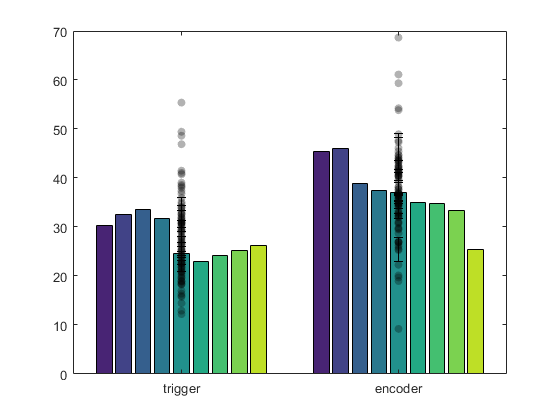

bar_chart(result_holdout);

## Test 1.3 : Test how good is the hyperparameter optimization

Without hyperparameter optimization, with hyperparameter optimization using Matlab's method, with hyperparameter optimization using my custom grid search method, 10 iterations, two behaviours

     1



The out-of-sample misclassification rate is 0.0161%
The out-of-sample misclassification rate is 6.43%
The out-of-sample misclassification rate is 0.017%
The out-of-sample misclassification rate is 8.15%
The out-of-sample misclassification rate is 0.0131%
The out-of-sample misclassification rate is 5.75%
The out-of-sample misclassification rate is 0.0126%
The out-of-sample misclassification rate is 6.88%
The out-of-sample misclassification rate is 0.0157%
The out-of-sample misclassification rate is 7.86%
The out-of-sample misclassification rate is 0.0145%
The out-of-sample misclassification rate is 7.65%
The out-of-sample misclassification rate is 0.0149%
The out-of-sample misclassification rate is 5.31%
The out-of-sample misclassification rate is 0.0159%
The out-of-sample misclassification rate is 6.97%
The out-of-sample misclassification rate is 0.0139%
The out-of-sample misclassification rate is 9.33%
The out-of-sample misclassification rate is 0.0161%
The out-of-sample misclassifica

     2



The out-of-sample misclassification rate is 0.00818%
The out-of-sample misclassification rate is 3.89%
The out-of-sample misclassification rate is 0.00824%
The out-of-sample misclassification rate is 3.69%
The out-of-sample misclassification rate is 0.00841%
The out-of-sample misclassification rate is 3.7%
The out-of-sample misclassification rate is 0.00854%
The out-of-sample misclassification rate is 5.79%
The out-of-sample misclassification rate is 0.00851%
The out-of-sample misclassification rate is 4.05%
The out-of-sample misclassification rate is 0.00924%
The out-of-sample misclassification rate is 3.97%
The out-of-sample misclassification rate is 0.00901%
The out-of-sample misclassification rate is 4.32%
The out-of-sample misclassification rate is 0.00783%
The out-of-sample misclassification rate is 4.21%
The out-of-sample misclassification rate is 0.0083%
The out-of-sample misclassification rate is 3.7%
The out-of-sample misclassification rate is 0.00812%
The out-of-sample miscl

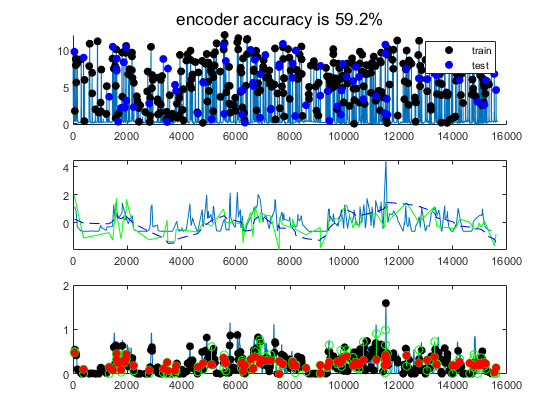

     3



Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |      16 | Accept |  9.1778e-05 |     0.62259 |  8.6775e-05 |   8.992e-05 |       225.38 |
|    2 |      16 | Best   |  8.6775e-05 |     0.53597 |  8.6775e-05 |   8.992e-05 |       4.6178 |
|    3 |      16 | Accept |  9.1261e-05 |       0.522 |  8.6775e-05 |   8.992e-05 |       3.5474 |
|    4 |       2 | Accept |  0.00018002 |     0.87671 |  8.2783e-05 |  8.5223e-05 |   8.6217e-06 |
|    5 |       2 | Accept |  0.00014401 |      1.4233 |  8.2783e-05 |  8.5223e-05 |     0.023053 |
|    6 |       2 | Accep

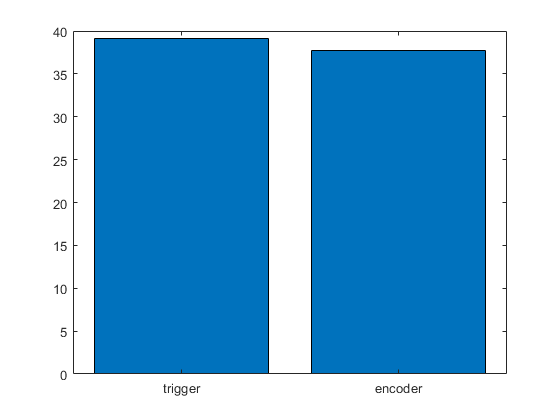

opti_range = [false, true, true];
method_list = {'', 'manual', 'native'};
render = [2,3,2];
result_hyper = {};
for idx = 1:numel(opti_range)  
    out = {}; disp(idx)
    for iter = 1:10
        out{iter} = predict_behaviours(obj, use_classifier, method, 'peaks_subtracted',{'trigger','encoder'}, '', 'optimize_hyper', opti_range(idx), 'optimization_method', method_list(idx), 'rendering',render(idx));
    end
    result_hyper{idx} = out;
end

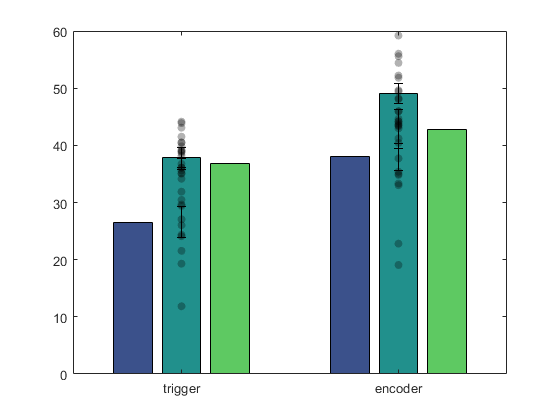

bar_chart(result_hyper);

## Test 1.4 : Test how good is the manual hyperparameter optimization for linear regression across behaviours

The out-of-sample misclassification rate is 3.92%
The out-of-sample misclassification rate is 0.388%
The out-of-sample misclassification rate is 1.07e+11%
The out-of-sample misclassification rate is 1.97e+09%
The out-of-sample misclassification rate is 3.34e+09%
The out-of-sample misclassification rate is 3.06e+10%
The out-of-sample misclassification rate is 1.14e+10%
The out-of-sample misclassification rate is 8.95e+11%
The out-of-sample misclassification rate is 3.78e+11%
The out-of-sample misclassification rate is 3.25e+10%
The out-of-sample misclassification rate is 8.67e+11%
The out-of-sample misclassification rate is 4.07e+11%
The out-of-sample misclassification rate is 0.00807%
The out-of-sample misclassification rate is 4.52%
The out-of-sample misclassification rate is 0.561%
The out-of-sample misclassification rate is 1.1e+11%
The out-of-sample misclassification rate is 1.89e+09%
The out-of-sample misclassification rate is 3.27e+09%
The out-of-sample misclassification rate is 

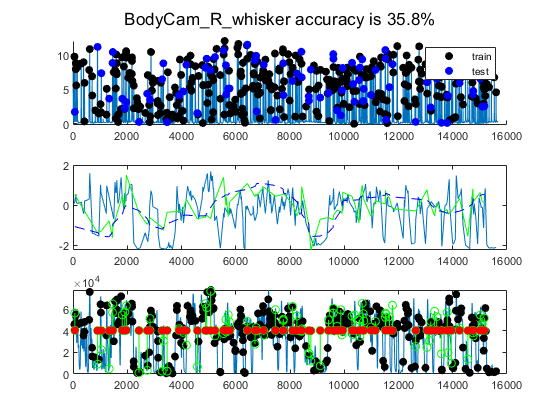

The out-of-sample misclassification rate is 1.17e+10%
The out-of-sample misclassification rate is 1.01e+12%


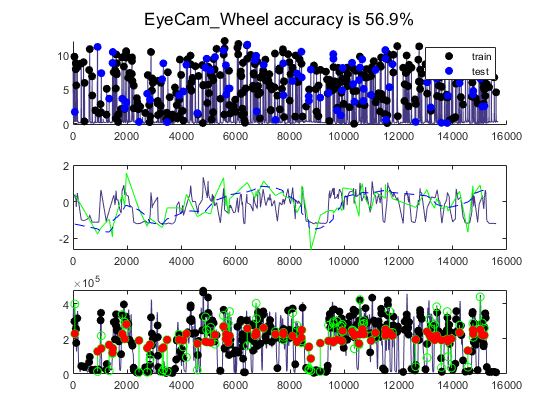

The out-of-sample misclassification rate is 3.93e+11%
The out-of-sample misclassification rate is 3.33e+10%


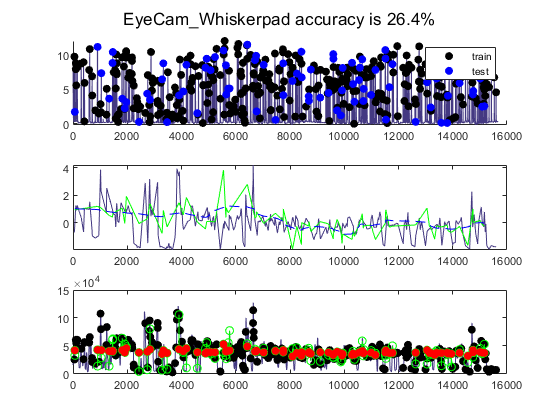

The out-of-sample misclassification rate is 9.35e+11%
The out-of-sample misclassification rate is 4.6e+11%


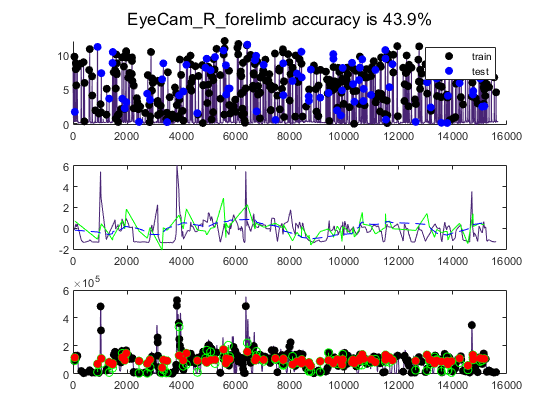

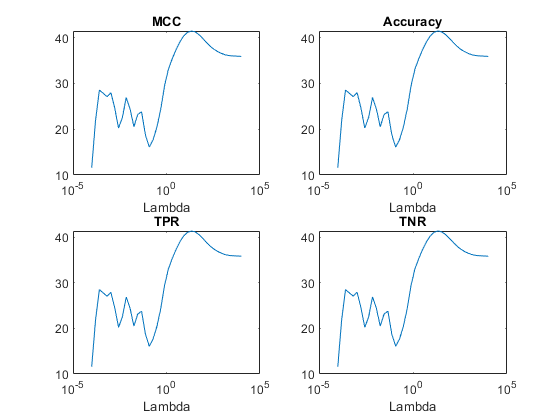

The out-of-sample misclassification rate is 0.00773%


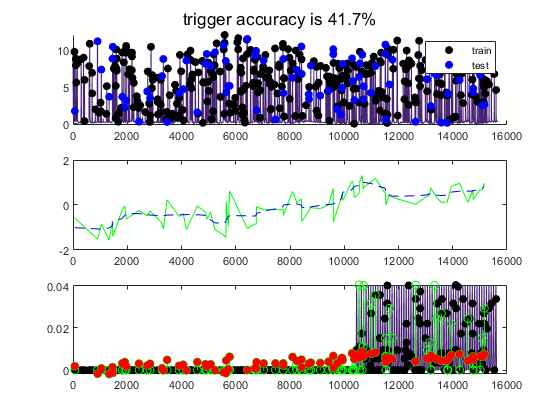

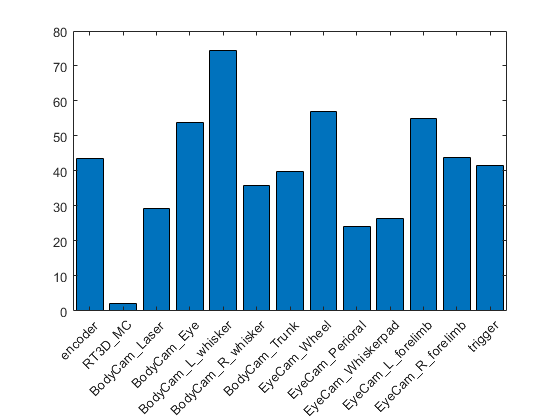

result_linear = {}; 
for iter = 1:10
    result_linear{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted','', '', 'optimize_hyper', true, 'optimization_method', 'manual', 'rendering',3);
end

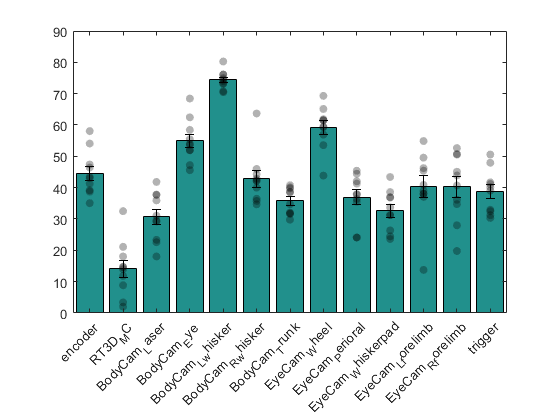

bar_chart(result_linear);

## Test 1.5 : Test how different solvers affect the prediction

     1



The out-of-sample misclassification rate is 0.00886%
The out-of-sample misclassification rate is 4.26%
The out-of-sample misclassification rate is 0.00959%
The out-of-sample misclassification rate is 3.91%
The out-of-sample misclassification rate is 0.00877%
The out-of-sample misclassification rate is 3.54%
The out-of-sample misclassification rate is 0.0101%
The out-of-sample misclassification rate is 4.24%
The out-of-sample misclassification rate is 0.0109%
The out-of-sample misclassification rate is 3.97%
The out-of-sample misclassification rate is 0.0119%
The out-of-sample misclassification rate is 3.99%
The out-of-sample misclassification rate is 0.00969%
The out-of-sample misclassification rate is 5.89%
The out-of-sample misclassification rate is 0.00838%
The out-of-sample misclassification rate is 4.26%
The out-of-sample misclassification rate is 0.00881%
The out-of-sample misclassification rate is 3.98%
The out-of-sample misclassification rate is 0.0086%
The out-of-sample miscla

     2



The out-of-sample misclassification rate is 0.0092%
The out-of-sample misclassification rate is 4.73%
The out-of-sample misclassification rate is 0.00868%
The out-of-sample misclassification rate is 4.8%
The out-of-sample misclassification rate is 0.0085%
The out-of-sample misclassification rate is 3.83%
The out-of-sample misclassification rate is 0.0106%
The out-of-sample misclassification rate is 3.25%
The out-of-sample misclassification rate is 0.00774%
The out-of-sample misclassification rate is 4.33%
The out-of-sample misclassification rate is 0.00829%
The out-of-sample misclassification rate is 4.91%
The out-of-sample misclassification rate is 0.011%
The out-of-sample misclassification rate is 4.09%
The out-of-sample misclassification rate is 0.0093%
The out-of-sample misclassification rate is 4.98%
The out-of-sample misclassification rate is 0.00824%
The out-of-sample misclassification rate is 4.35%
The out-of-sample misclassification rate is 0.0081%
The out-of-sample misclassif

     3



The out-of-sample misclassification rate is 0.0103%
The out-of-sample misclassification rate is 4.45%
The out-of-sample misclassification rate is 0.00875%
The out-of-sample misclassification rate is 3.97%
The out-of-sample misclassification rate is 0.00848%
The out-of-sample misclassification rate is 4.1%
The out-of-sample misclassification rate is 0.0085%
The out-of-sample misclassification rate is 4.09%
The out-of-sample misclassification rate is 0.00752%
The out-of-sample misclassification rate is 5.45%
The out-of-sample misclassification rate is 0.00881%
The out-of-sample misclassification rate is 4.09%
The out-of-sample misclassification rate is 0.0098%
The out-of-sample misclassification rate is 4.45%
The out-of-sample misclassification rate is 0.00959%
The out-of-sample misclassification rate is 4.25%
The out-of-sample misclassification rate is 0.00856%
The out-of-sample misclassification rate is 5.08%
The out-of-sample misclassification rate is 0.00852%
The out-of-sample miscla

     4



The out-of-sample misclassification rate is 0.00913%
The out-of-sample misclassification rate is 4.18%
The out-of-sample misclassification rate is 0.0132%
The out-of-sample misclassification rate is 3.84%
The out-of-sample misclassification rate is 0.00902%
The out-of-sample misclassification rate is 3.78%
The out-of-sample misclassification rate is 0.00799%
The out-of-sample misclassification rate is 4.05%
The out-of-sample misclassification rate is 0.00895%
The out-of-sample misclassification rate is 3.44%
The out-of-sample misclassification rate is 0.0078%
The out-of-sample misclassification rate is 4.55%
The out-of-sample misclassification rate is 0.00983%
The out-of-sample misclassification rate is 4.22%
The out-of-sample misclassification rate is 0.00847%
The out-of-sample misclassification rate is 5.32%
The out-of-sample misclassification rate is 0.00911%
The out-of-sample misclassification rate is 4.22%
The out-of-sample misclassification rate is 0.00786%
The out-of-sample misc

     5



The out-of-sample misclassification rate is 0.00805%
The out-of-sample misclassification rate is 4.51%
The out-of-sample misclassification rate is 0.00873%
The out-of-sample misclassification rate is 3.67%
The out-of-sample misclassification rate is 0.0106%
The out-of-sample misclassification rate is 3.94%
The out-of-sample misclassification rate is 0.00794%
The out-of-sample misclassification rate is 4.02%
The out-of-sample misclassification rate is 0.0108%
The out-of-sample misclassification rate is 3.88%
The out-of-sample misclassification rate is 0.0112%
The out-of-sample misclassification rate is 4.08%
The out-of-sample misclassification rate is 0.00812%
The out-of-sample misclassification rate is 3.98%
The out-of-sample misclassification rate is 0.00885%
The out-of-sample misclassification rate is 4.02%
The out-of-sample misclassification rate is 0.00876%
The out-of-sample misclassification rate is 3.75%
The out-of-sample misclassification rate is 0.00861%
The out-of-sample miscl

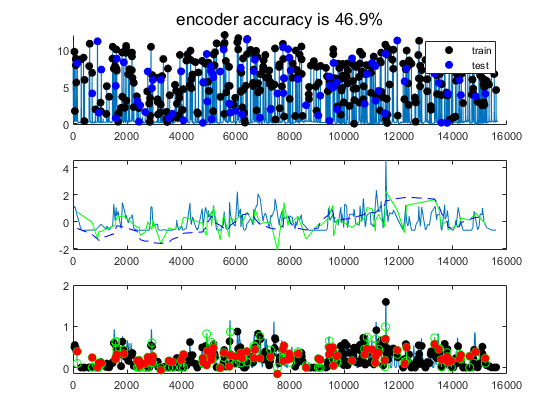

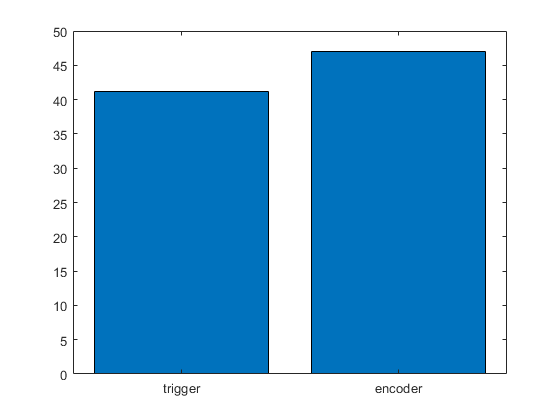

solver_list = {'sgd','asgd','lbfgs',{'sgd','lbfgs'},{'asgd','lbfgs'}};
result_solver = {};
for idx = 1:numel(solver_list)  
    out = {}; disp(idx)
    for iter = 1:10
        out{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'trigger','encoder'}, '', 'optimize_hyper', true, 'optimization_method', 'manual', 'rendering',3, 'Solver', solver_list(idx));
    end
    result_solver{idx} = out;
end
bar_chart(result_solver);

# 2. Test the effect of shuffling

## Test 2.1 : Test the effect of behaviour shuffling

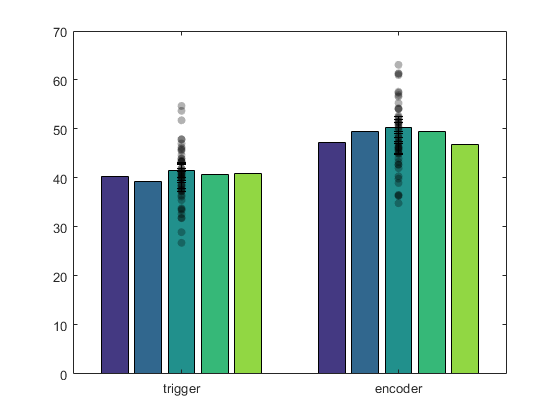

% Using the entire dendritic tree on the encoder

multirunRL = {};
for iter = 1:10
    multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual');
end
bar_chart(multirunRL);

## Test 2.2 : Test the effect of shuffling predictor timpoints

% Using the entire dendritic tree on the encoder
multirunRL = {};
for iter = 1:10

block_size = 100

The out-of-sample misclassification rate is 4.81%
The out-of-sample misclassification rate is 3.36e+09%
The out-of-sample misclassification rate is 1.32e+10%


block_size = 100

The out-of-sample misclassification rate is 4.82%
The out-of-sample misclassification rate is 5.58e+09%
The out-of-sample misclassification rate is 7.16e+09%


block_size = 100

The out-of-sample misclassification rate is 4.19%
The out-of-sample misclassification rate is 3.53e+09%
The out-of-sample misclassification rate is 8.9e+09%


block_size = 100

The out-of-sample misclassification rate is 4.39%
The out-of-sample misclassification rate is 2.97e+09%
The out-of-sample misclassification rate is 1.31e+10%


block_size = 100

The out-of-sample misclassification rate is 3.5%
The out-of-sample misclassification rate is 3.5e+09%
The out-of-sample misclassification rate is 9.09e+09%


block_size = 100

The out-of-sample misclassification rate is 5.06%
The out-of-sample misclassification rate is 3.43e+09%
The out-of-sample misclassification rate is 8.39e+09%


block_size = 100

The out-of-sample misclassification rate is 4.22%
The out-of-sample misclassification rate is 3.97e+09%
The out-of-sample misclassification rate is 7.59e+09%


block_size = 100

The out-of-sample misclassification rate is 3.86%
The out-of-sample misclassification rate is 3.46e+09%
The out-of-sample misclassification rate is 7.97e+09%


block_size = 100

The out-of-sample misclassification rate is 4.01%
The out-of-sample misclassification rate is 4.22e+09%
The out-of-sample misclassification rate is 7.73e+09%


block_size = 100

The out-of-sample misclassification rate is 4.58%
The out-of-sample misclassification rate is 3.79e+09%
The out-of-sample misclassification rate is 1.4e+10%


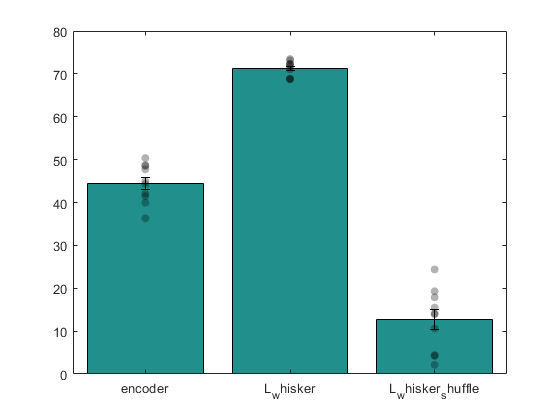

    multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual','shuffling','events');

end
bar_chart(multirunRL);

## Test 2.3 : Test the effect of shuffling modulation values

block_size = 100

The out-of-sample misclassification rate is 4.89%
The out-of-sample misclassification rate is 7.25e+09%
The out-of-sample misclassification rate is 8.22e+09%


block_size = 100

The out-of-sample misclassification rate is 4.99%
The out-of-sample misclassification rate is 7.75e+09%
The out-of-sample misclassification rate is 8.05e+09%


block_size = 100

The out-of-sample misclassification rate is 5.82%
The out-of-sample misclassification rate is 1.06e+10%
The out-of-sample misclassification rate is 8.04e+09%


block_size = 100

The out-of-sample misclassification rate is 12.1%
The out-of-sample misclassification rate is 6.96e+09%
The out-of-sample misclassification rate is 7.78e+09%


block_size = 100

The out-of-sample misclassification rate is 5.34%
The out-of-sample misclassification rate is 9.38e+09%
The out-of-sample misclassification rate is 7.49e+09%


block_size = 100

The out-of-sample misclassification rate is 4.78%
The out-of-sample misclassification rate is 7.64e+09%
The out-of-sample misclassification rate is 8.71e+09%


block_size = 100

The out-of-sample misclassification rate is 18.3%
The out-of-sample misclassification rate is 1.36e+10%
The out-of-sample misclassification rate is 8.1e+09%


block_size = 100

The out-of-sample misclassification rate is 6.48%
The out-of-sample misclassification rate is 7.5e+09%
The out-of-sample misclassification rate is 7.19e+09%


block_size = 100

The out-of-sample misclassification rate is 5.52%
The out-of-sample misclassification rate is 1.06e+10%
The out-of-sample misclassification rate is 8.85e+09%


block_size = 100

The out-of-sample misclassification rate is 7.66%


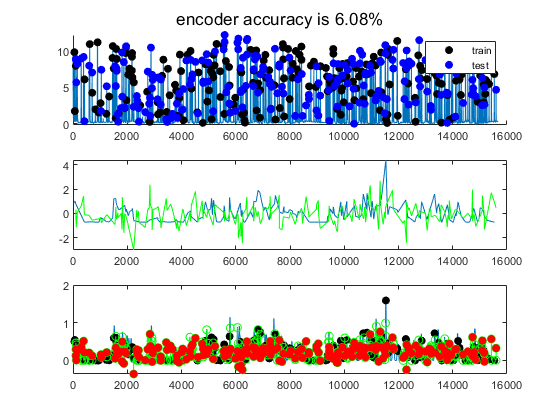

The out-of-sample misclassification rate is 1.19e+10%


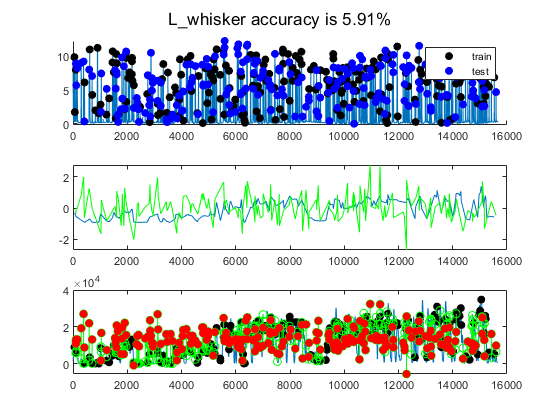

The out-of-sample misclassification rate is 9.13e+09%


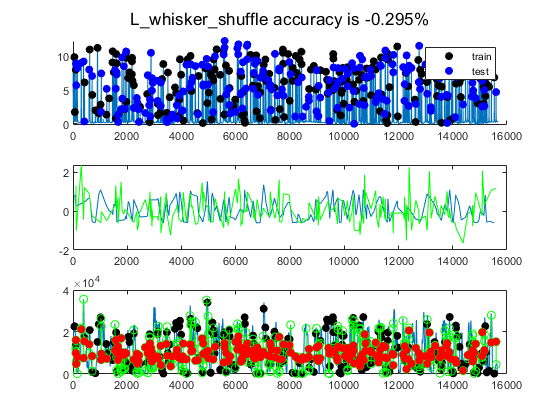

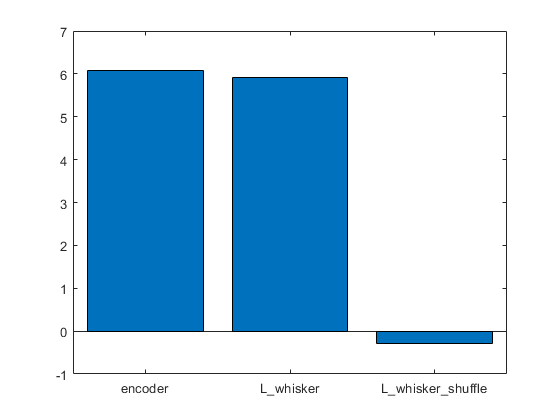

% Using the entire dendritic tree on the encoder
multirunRL = {};
for iter = 1:10
    multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual','shuffling','ROIs');
end

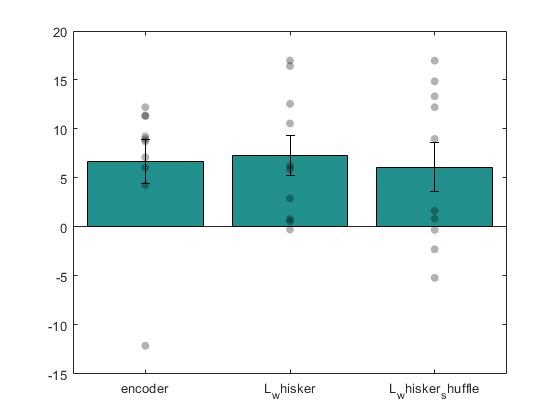

bar_chart(multirunRL);

## Test 2.4 : Full shuffling

block_size = 100

The out-of-sample misclassification rate is 21.4%
The out-of-sample misclassification rate is 7.49e+09%
The out-of-sample misclassification rate is 1.52e+10%


block_size = 100

The out-of-sample misclassification rate is 6.03%
The out-of-sample misclassification rate is 7e+09%
The out-of-sample misclassification rate is 1.46e+10%


block_size = 100

The out-of-sample misclassification rate is 5.69%
The out-of-sample misclassification rate is 1.3e+10%
The out-of-sample misclassification rate is 8.41e+09%


block_size = 100

The out-of-sample misclassification rate is 31.1%
The out-of-sample misclassification rate is 9.39e+09%
The out-of-sample misclassification rate is 7.92e+09%


block_size = 100

The out-of-sample misclassification rate is 28.6%
The out-of-sample misclassification rate is 1.03e+10%
The out-of-sample misclassification rate is 7.58e+09%


block_size = 100

The out-of-sample misclassification rate is 4.2%
The out-of-sample misclassification rate is 7.42e+09%
The out-of-sample misclassification rate is 1.22e+10%


block_size = 100

The out-of-sample misclassification rate is 6.21%
The out-of-sample misclassification rate is 9.97e+09%
The out-of-sample misclassification rate is 6.09e+09%


block_size = 100

The out-of-sample misclassification rate is 4.41%
The out-of-sample misclassification rate is 7.35e+09%
The out-of-sample misclassification rate is 9.93e+09%


block_size = 100

The out-of-sample misclassification rate is 12.7%
The out-of-sample misclassification rate is 7.12e+09%
The out-of-sample misclassification rate is 1.31e+10%


block_size = 100

The out-of-sample misclassification rate is 5.14%


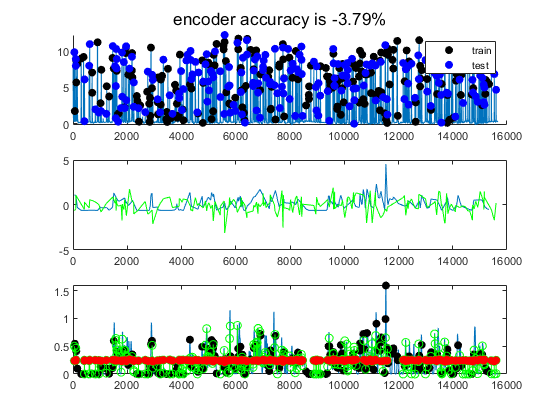

The out-of-sample misclassification rate is 7.15e+09%


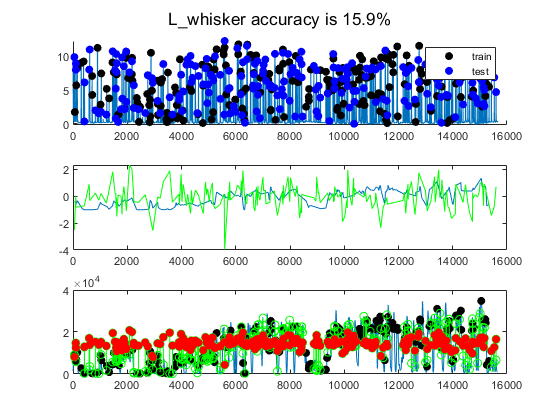

The out-of-sample misclassification rate is 8.72e+09%


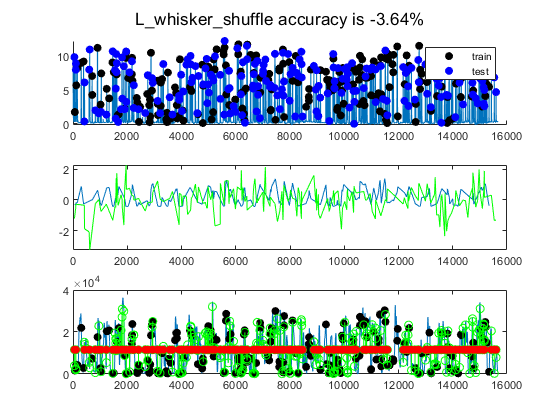

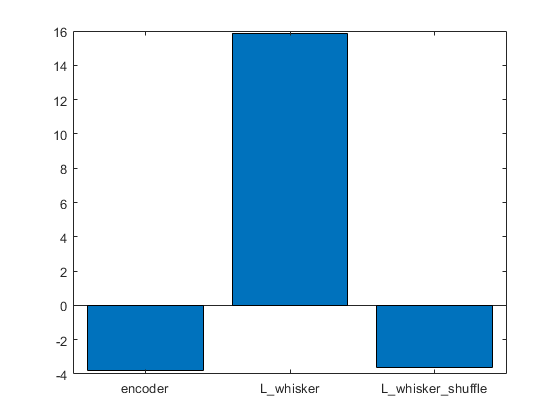

% Using the entire dendritic tree on the encoder
multirunRL = {};
for iter = 1:10
    multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual','shuffling','both');
end

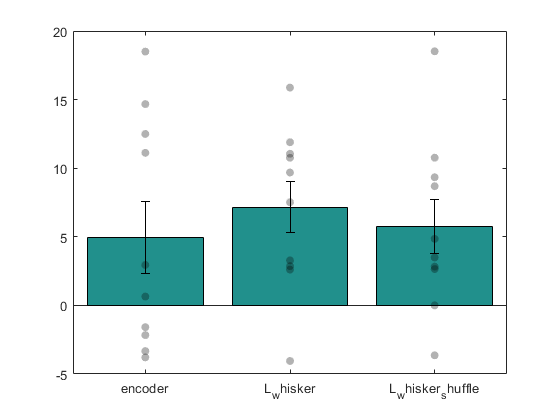

bar_chart(multirunRL);

# 3. Extract the beta coefficients

## Test 3.1 : Test how good is the manual hyperparameter optimization for linear regression across behaviours

block_size = 100

The out-of-sample misclassification rate is 4.55%
The out-of-sample misclassification rate is 7.13e+09%
The out-of-sample misclassification rate is 1.06e+10%


block_size = 100

The out-of-sample misclassification rate is 5.2%
The out-of-sample misclassification rate is 6.78e+09%
The out-of-sample misclassification rate is 1.5e+10%


block_size = 100

The out-of-sample misclassification rate is 4.01%
The out-of-sample misclassification rate is 7.05e+09%
The out-of-sample misclassification rate is 7.33e+09%


block_size = 100

The out-of-sample misclassification rate is 19.8%
The out-of-sample misclassification rate is 7.7e+09%
The out-of-sample misclassification rate is 1.01e+10%


block_size = 100

The out-of-sample misclassification rate is 7.21%
The out-of-sample misclassification rate is 1.56e+10%
The out-of-sample misclassification rate is 6.52e+09%


block_size = 100

The out-of-sample misclassification rate is 4.71%
The out-of-sample misclassification rate is 1.65e+10%
The out-of-sample misclassification rate is 8.57e+09%


block_size = 100

The out-of-sample misclassification rate is 20.9%
The out-of-sample misclassification rate is 1.11e+10%
The out-of-sample misclassification rate is 7.95e+09%


block_size = 100

The out-of-sample misclassification rate is 4.77%
The out-of-sample misclassification rate is 8.39e+09%
The out-of-sample misclassification rate is 1.1e+10%


block_size = 100

The out-of-sample misclassification rate is 4.36%
The out-of-sample misclassification rate is 7.49e+09%
The out-of-sample misclassification rate is 1.95e+10%


block_size = 100

The out-of-sample misclassification rate is 4.84%


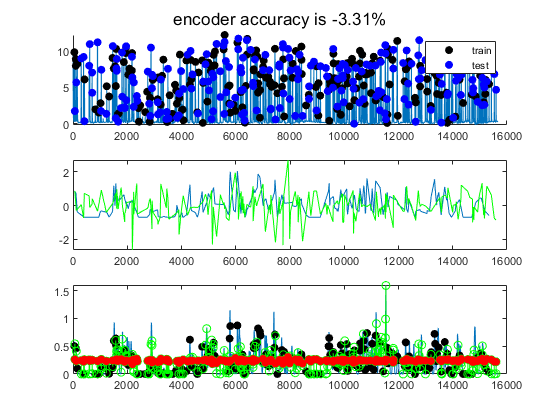

The out-of-sample misclassification rate is 7.51e+09%


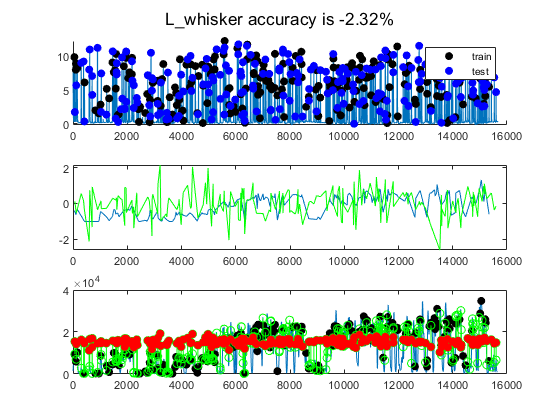

The out-of-sample misclassification rate is 1.56e+10%


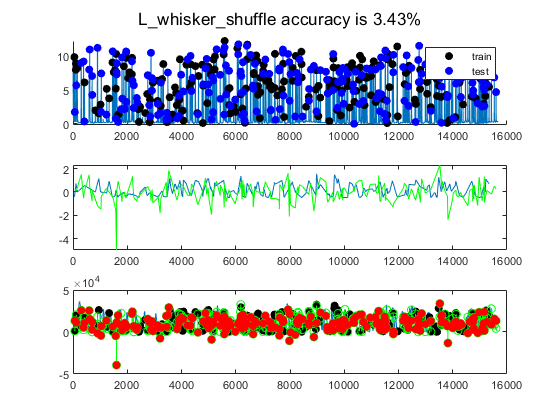

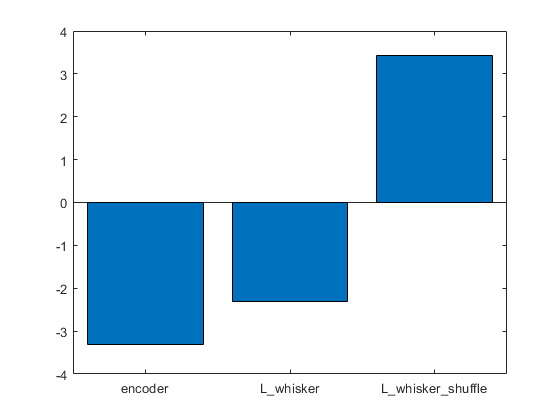

result_beta = {};
for iter = 1:20
     result_beta{iter} = predict_behaviours(obj, false, 'linear', 'peaks_rescaled','', '', 'optimize_hyper', true, 'optimization_method', 'manual', 'rendering',0);
end

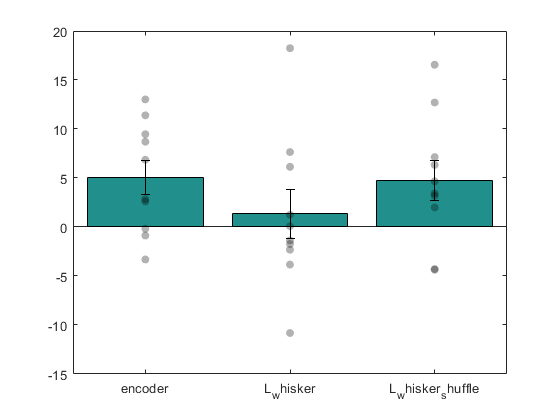

bar_chart(result_beta);

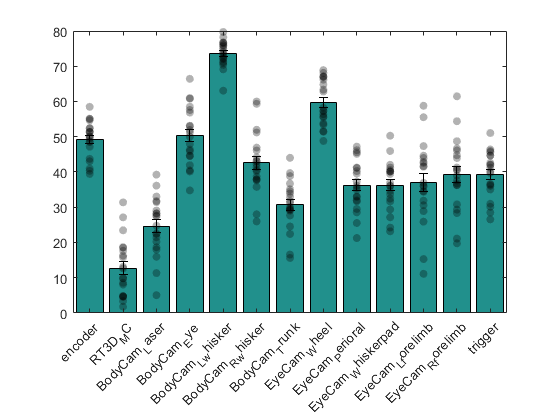

for beh_idx = 1:numel(result_beta{1}.beh_type)
    betas   = [];
    for iter = 1:numel(result_beta)
        model = result_beta{iter}.model{beh_idx};
        for trained_idx = 1:numel(model.Trained)
            mdl = model.Trained{trained_idx};                        
            betas(trained_idx, :) = mdl.Beta;
        end
    end

ans = 'encoder'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

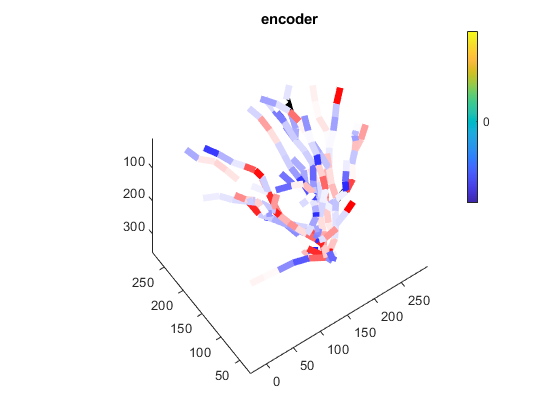

ans = 'RT3D_MC'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

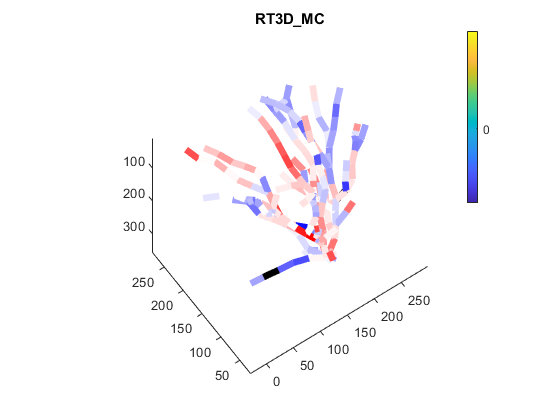

ans = 'BodyCam_Laser'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

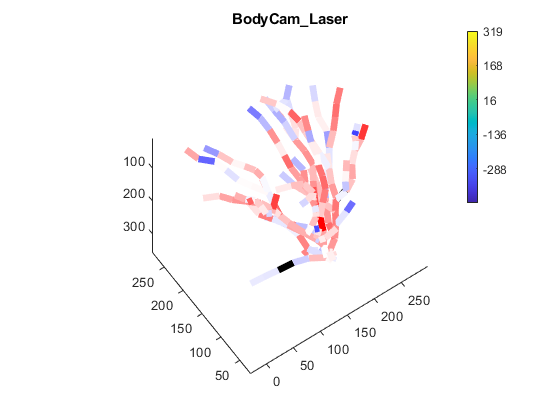

ans = 'BodyCam_Eye'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

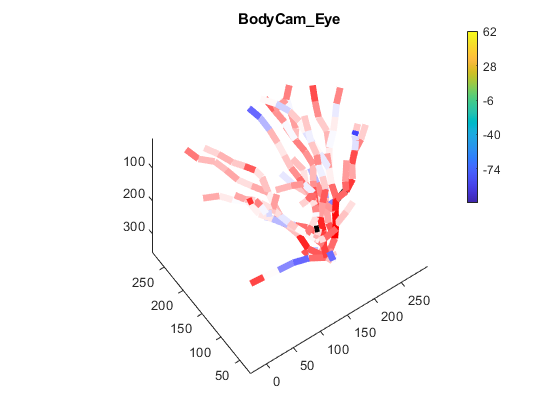

ans = 'BodyCam_L_whisker'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

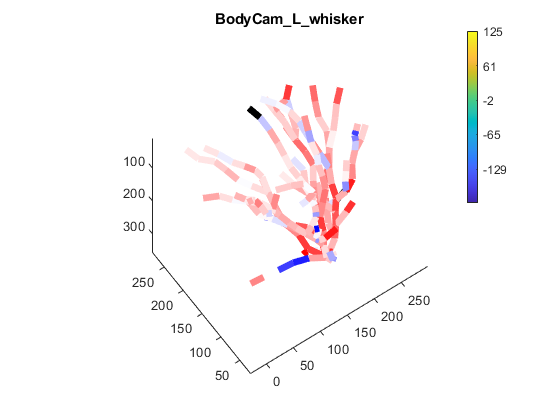

ans = 'BodyCam_R_whisker'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

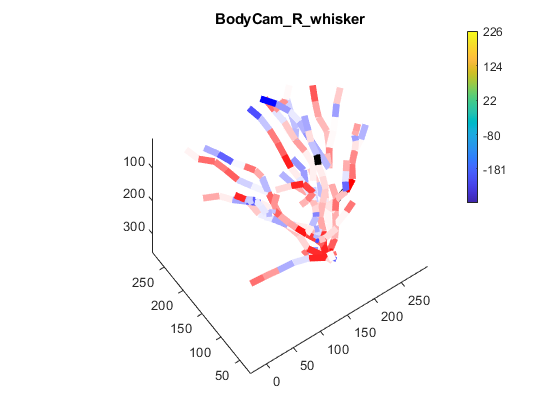

ans = 'BodyCam_Trunk'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

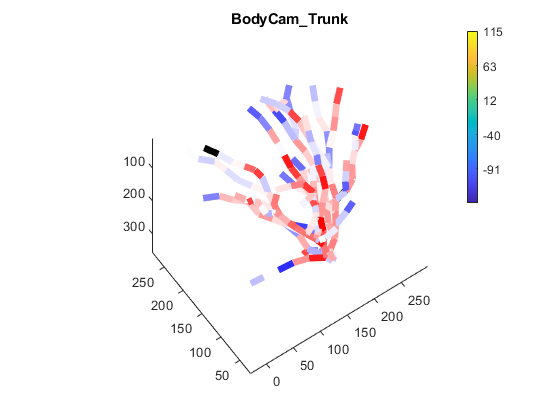

ans = 'EyeCam_Wheel'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

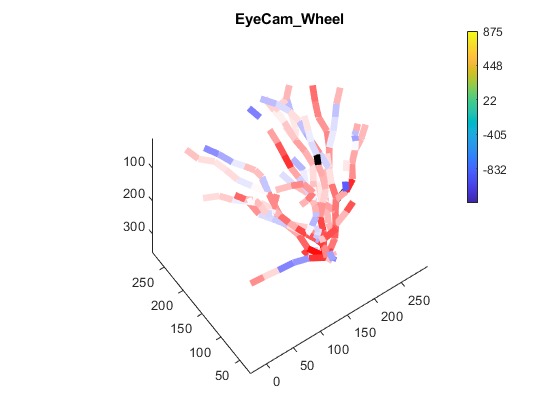

ans = 'EyeCam_Perioral'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

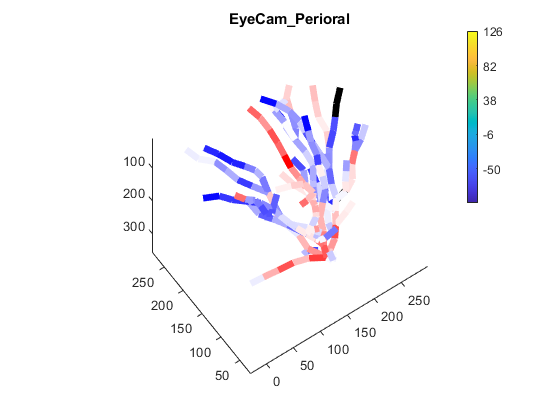

ans = 'EyeCam_Whiskerpad'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

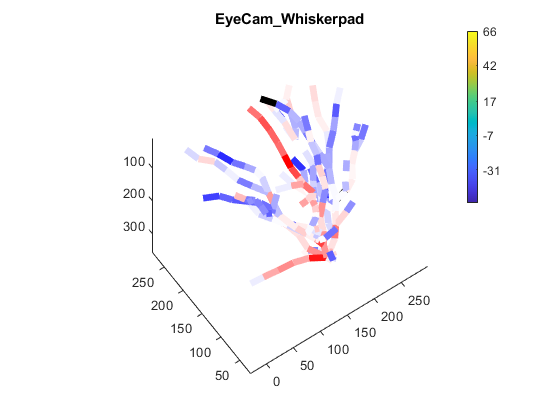

ans = 'EyeCam_L_forelimb'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

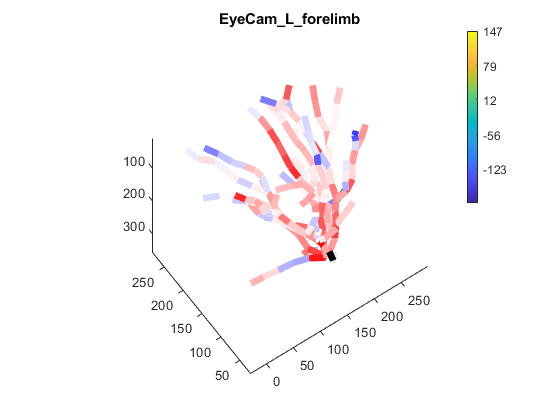

ans = 'EyeCam_R_forelimb'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

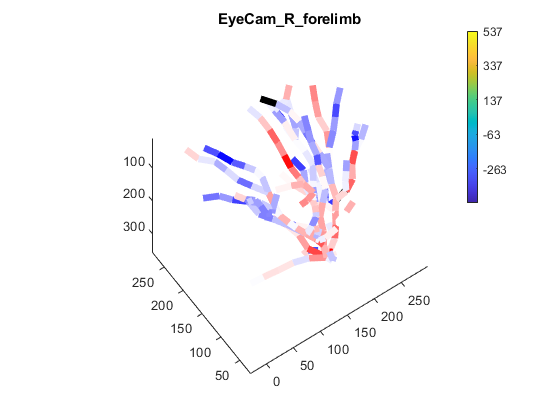

ans = 'trigger'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

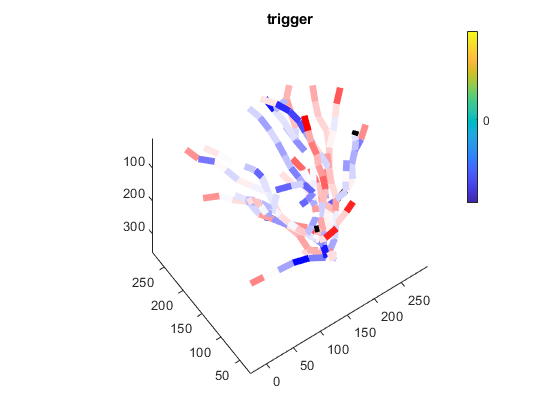

    result_beta{1}.beh_type{beh_idx}
    next_fig
    obj.ref.plot_value_tree(mean(betas,1), find(~ismember(obj.ref.indices.valid_swc_rois, obj.bad_ROI_list)),'',strrep(result_beta{1}.beh_type{beh_idx},'_','\_'),'',beh_idx,'','redblue', 'invalid_color_symetrical');
end

Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |      18 | Best   |      21.982 |      1.5904 |      21.982 |      21.982 |        181.9 |
|    2 |      17 | Best   |      21.943 |      1.8555 |      21.943 |      21.975 |       43.502 |
|    3 |      17 | Accept |      21.998 |      1.6391 |      21.943 |      21.975 |       205.32 |
|    4 |       3 | Accept |      21.897 |      2.0089 |      21.863 |      21.924 |   6.6285e-07 |
|    5 |       3 | Accept |       21.92 |      2.0006 |      21.863 |      21.924 |       25.044 |
|    6 |       3 | Accep

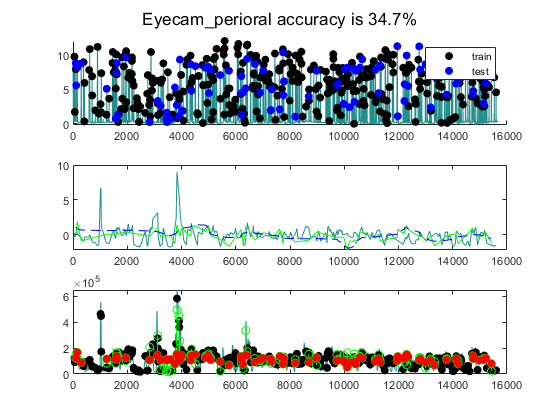

a = {};
for iter = 1:10
     a{iter} = predict_behaviours(obj, false, 'linear', 'peaks_rescaled',{'Eyecam_perioral'}, '', 'optimize_hyper', true, 'optimization_method', 'native', 'rendering',2);
end

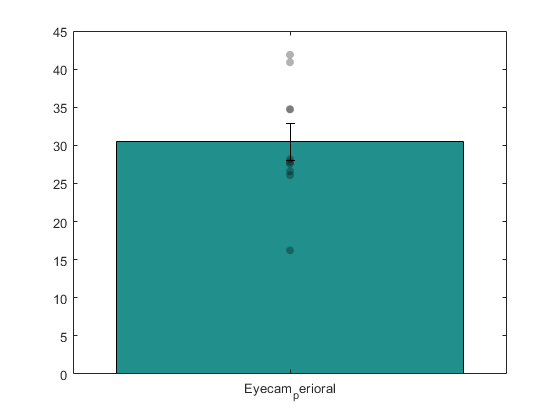

bar_chart(a);

ans = 'Eyecam_perioral'

ans = 24

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

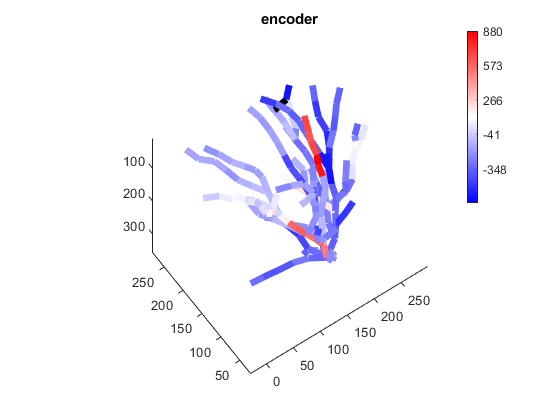

for beh_idx = 1:numel(a{1}.beh_type)
    betas   = [];
    for iter = 1:numel(a)
        model = a{iter}.model{beh_idx};
        for trained_idx = 1:numel(model.Trained)
            mdl = model.Trained{trained_idx};                        
            betas(iter, trained_idx, :) = mdl.Beta;
        end
    end
    a{1}.beh_type{beh_idx}
    next_fig
    obj.ref.plot_value_tree(mean(betas,1), find(~ismember(obj.ref.indices.valid_swc_rois, obj.bad_ROI_list)),'',strrep(result_beta{1}.beh_type{beh_idx},'_','\_'),'',beh_idx,'','redblue', 'invalid_color_symetrical');
end








% plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
